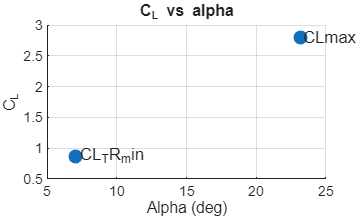

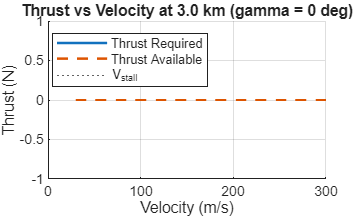

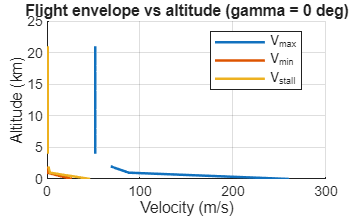


---- Flight envelope: gamma = 5 deg ----
V_TR_min = 83.12 m/s, V_stall = Inf m/s
Vmin (TA=TR) = NaN m/s, Vmax (TA=TR) = NaN m/s

For CL_TR_min = 0.8660:
  alpha = 7.050 deg, delta_e = 3.675 deg

For CLmax = 2.8000:
  alpha = 23.167 deg, delta_e = 14.036 deg


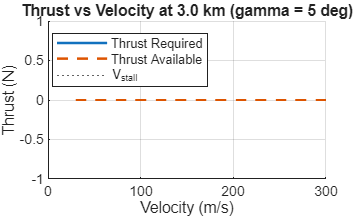

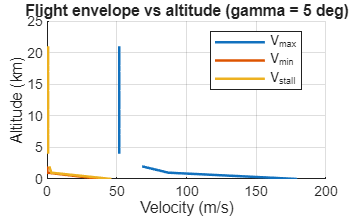

clc;

clearvars;

% Given data
W = 33135 * 9.8; % N
S = 88.26; % m^2 WingArea
AR = 5.9; 
Fmax = 12700 * 9.8; % N
TSFC = 0.155; % kg/N-hr
n = 2;

 gamma = 0; % STEADY
 flightEnvelope(gamma);

V_TR_min: 83.283
V_stall: 53.7626
Vmin: 33.8755
Vmax: 275.8684




 gamma = 5; % CLIMB
 flightEnvelope(gamma);

function flightEnvelope(gamma)

% Given data
W = 33135 * 9.8; % N
S = 88.26; % m^2 WingArea

rho_ssl = 1.225; % kg/m^3

CD0 = 0.015; 
k = 0.02; 
CLmax = 2.8; 
Tmax = 2 * 27.8 * 1000;

height = 3;
atmosphere_data = atm_table(height);

% Extracting density values from the atmospheric data
V = 30:0.01:300;
rho = atmosphere_data(height+1,5);
   
% for min. Thrust
CL_TR_min = sqrt(CD0 / k);
CD_TR_min = CD0 + k * CLmax^2;
TR_min = W * (CD_TR_min / CL_TR_min);
V_TR_min = sqrt((2 * W * cosd(gamma)) / (rho_ssl * S * CL_TR_min));
disp(['V_TR_min: ', num2str(V_TR_min)]);
Vstall = sqrt((2 * W * cosd(gamma)) / (rho * S * CLmax));
disp(['V_stall: ', num2str(Vstall)]);

% for twin engine @ full throttle power setting
pi = 1;
Ta = (pi * (rho ./ rho_ssl).^0.6 * Tmax);
wingloading = W / S;
T2W = Ta / W;
U = (T2W)^2 - (4 * CD0 * k);
% Vmax = sqrt(((T2W + sqrt(U)) .* wingloading) / (rho .* CD0));
% Vmin = sqrt(((T2W - sqrt(U)) .* wingloading) / (rho .* CD0));

% Coefficients of the quadratic equation
a = 0.5 * rho * S * CD0;
b = 0;
c = W * sind(gamma) - Ta;
d = 0;
e = k * (W * cosd(gamma))^2 / (0.5 * rho * S);

% Coefficient vector
coefficients = [a, b, c, d, e];

% Calculate the roots
roots_of_quadratic = roots(coefficients);

% Access 2nd and 4th roots
Vmax_h = real(roots_of_quadratic(2));
Vmin_h = real(roots_of_quadratic(4));

disp(['Vmin: ', num2str(Vmin_h)]);
disp(['Vmax: ', num2str(Vmax_h)]);
fprintf('\n');

CL_Vmin = 2*W*cosd(gamma)/ (rho*S*(Vmin_h^2));
CL_Vmax = 2*W*cosd(gamma)/ (rho*S*(Vmax_h^2));

% Generate vectors for velocity and thrust
D = (0.5 * rho .* (V.^2) * S * CD0) + ((2 * k * (W * cosd(gamma))^2) ./ (rho * S * V.^2));
TR = D + W * sind(gamma);
TA = Ta * ones(size(V));

% Given values and their labels
CL_values = [CL_TR_min, CLmax, CL_Vmin, CL_Vmax];
CL_labels = {'CL_TR_min', 'CLmax' , 'CL_Vmin','CL_Vmax'};

% Initialize arrays to store results
alpha_values = zeros(size(CL_values));
delta_e_values = zeros(size(CL_values));

figure; hold on;

for i = 1:length(CL_values)
    % Given values for this iteration
    CL = CL_values(i);
    % Equation for alpha in terms of CL
    alpha_CL = (CL - 0.02) / 0.12;
    
    % Equation for delta_e assuming CM = 0
    syms delta_e;
    CM = 0.24 - 0.18 * alpha_CL + 0.28 * delta_e;
    delta_e_CL = solve(CM == 0, delta_e);

    % Store results
    alpha_values(i) = alpha_CL;
    delta_e_values(i) = double(delta_e_CL);

    % Display the results with the label
    fprintf('\n');
    fprintf('For %s = %.4f:\n', CL_labels{i}, CL);
    fprintf('Alpha: %.4f deg \n',alpha_CL);
    fprintf('Delta_e: %.4f deg \n', delta_e_values(i));
    fprintf('\n');

    % Plot CL against alpha
    plot(CL ,alpha_CL,  'o', 'DisplayName', CL_labels{i});
    
end

% Add labels and legend to the plot
xlabel('Alpha (deg)');
ylabel('CL');
legend('Location', 'Best');
title('CL vs Alpha for Different CL Values');
grid on;


% Plot the results
figure;
plot(V, TR, 'DisplayName', 'Thrust Required', 'LineWidth', 1.5);
hold on;
plot(V, TA, 'DisplayName', 'Thrust Available', 'LineWidth', 1.5);
plot([Vmin_h, Vmin_h], [0, max(TR)], '--', 'DisplayName', 'V_{min}');
plot([Vstall, Vstall], [0, max(TR)], '--', 'DisplayName', 'V_{stall}');
plot([V_TR_min, V_TR_min], [0, max(TR)], '--', 'DisplayName', 'V_{Tmin}');
plot([Vmax_h, Vmax_h], [0, max(TR)], '--', 'DisplayName', 'V_{max}');
hold off;

% Set labels and legend
xlabel('Velocity (m/s)');
ylabel('Thrust (N)');
legend('show');
title(['Thrust vs Velocity at Altitude ', num2str(height), ' km']);

%-----------------------------------------------------------------------------%

    % Define the altitude range
    altitude_range = 0:1:21;

    % Initialize arrays
    Ta = zeros;
    TA = zeros;
    T2W = zeros;
    U = zeros;
    Vstall = zeros;
    Vmax = zeros;
    Vmin = zeros;
    rho_h = zeros;

    % Calculation for different altitudes
    for i = 1:length(altitude_range) 
        x = atm_table(i);
        rho_h(i) = x(i,5);
        wingloading = W*cosd(gamma) / S;
        Ta(i) =  (pi * (rho_h(i)./rho_ssl).^0.6 * Tmax);
        T2W(i) = (Ta(i)-W*sind(gamma))/W*cosd(gamma);
        U(i) = (T2W(i))^2 - (4*CD0*k);

        Vmax(i) = real(sqrt(((T2W(i) + sqrt(U(i))) .* wingloading) / (rho_h(i).* CD0)));
        Vmin(i) = real(sqrt(((T2W(i) - sqrt(U(i))) .* wingloading) / (rho_h(i) .* CD0)));
 
        Vstall(i) = sqrt((2 * W * cosd(gamma)) / (rho_h(i) * S * CLmax));
        TA = Ta(i) * ones(size(V));
    end

    % Add labels to the altitude plot
    figure;
    plot(Vmax, altitude_range);
    hold on;
    plot(Vmin, altitude_range);
    hold on;
    plot(Vstall, altitude_range);
    hold off;

    % Set labels and legend for altitude plot
    xlabel('Velocity (m/s)');
    ylabel('Altitude (km)');
    legend('V_{max}', 'V_{min}', 'V_{stall}');
    title('Flight envelope');

    
%full flight envelope
V_min_hf=zeros;
V_max_hf=zeros;
V_stall_hf=zeros;
Rho_hf=zeros;
hf=0:1:21;
Gamma=0:1:10;

for j=1:length(Gamma)
    for i=1:length(hf)
        
    x = atm_table(i);
    Rho_hf(i)=x(i+1,5);
    TA_max_h(i)=1*((Rho_hf(i)/rho_ssl)^0.6)*Tmax;
   
    V_min_hf(i,j)=real(sqrt((((TA_max_h(i)-W*sind(Gamma(j)))/S)-sqrt((((TA_max_h(i)-W*sind(Gamma(j)))/W*cosd(Gamma(j)))^2)-(4*CD0*k))*(W*cosd(Gamma(j))/S))/(Rho_hf(i)*CD0)));
    V_max_hf(i,j)=real(sqrt((((TA_max_h(i)-W*sind(Gamma(j)))/S)+sqrt((((TA_max_h(i)-W*sind(Gamma(j)))/W*cosd(Gamma(j)))^2)-(4*CD0*k))*(W*cosd(Gamma(j))/S))/(Rho_hf(i)*CD0)));
    V_stall_hf(i,j)=sqrt(2*W*cosd(Gamma(j))/(Rho_hf(i)*S*CLmax));

    end
end
figure;
surf(V_max_hf, 'FaceColor', '#4DBEEE');
hold on;
surf(V_min_hf, 'FaceColor', '#77AC30'); 
hold on;
surf(V_stall_hf, 'FaceColor', '#EDB120'); 

xlabel('Flight Path Angle (deg)');
ylabel('Height (m)');
zlabel('Velocity (m/s)');
title('Full Flight Envelope');

% Add a color legend
legend({'V_{max}', 'V_{min}', 'V_{stall}'}, 'Location', 'eastoutside');

% Customize the view angle
view(3); % 3D view

end
 


